# 06 Homework: Isoparametric Finite Elements

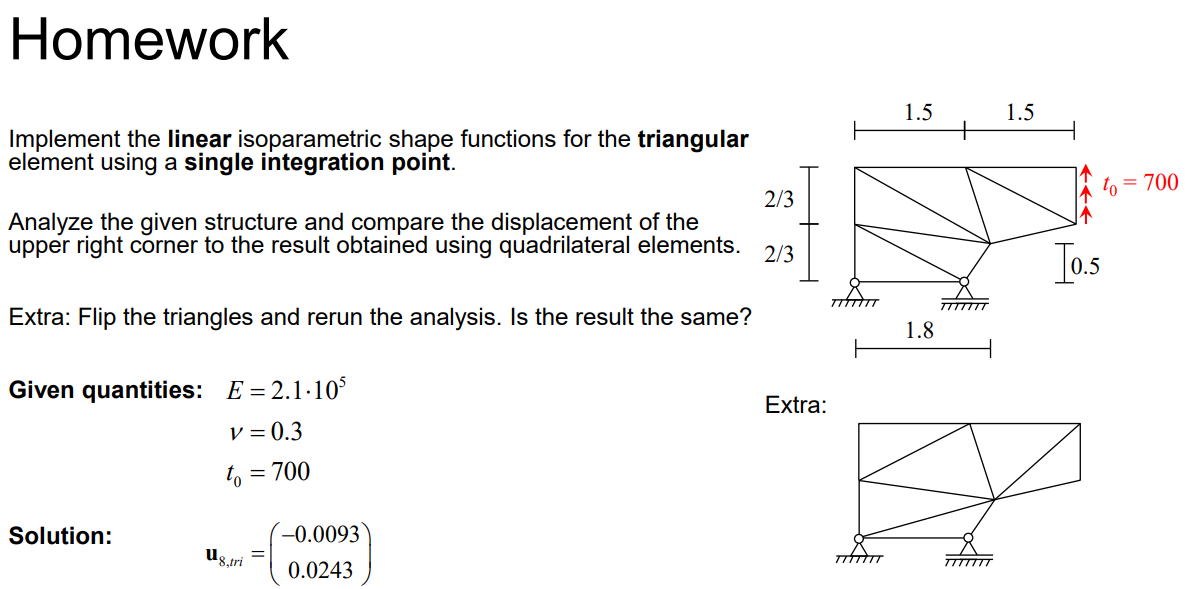

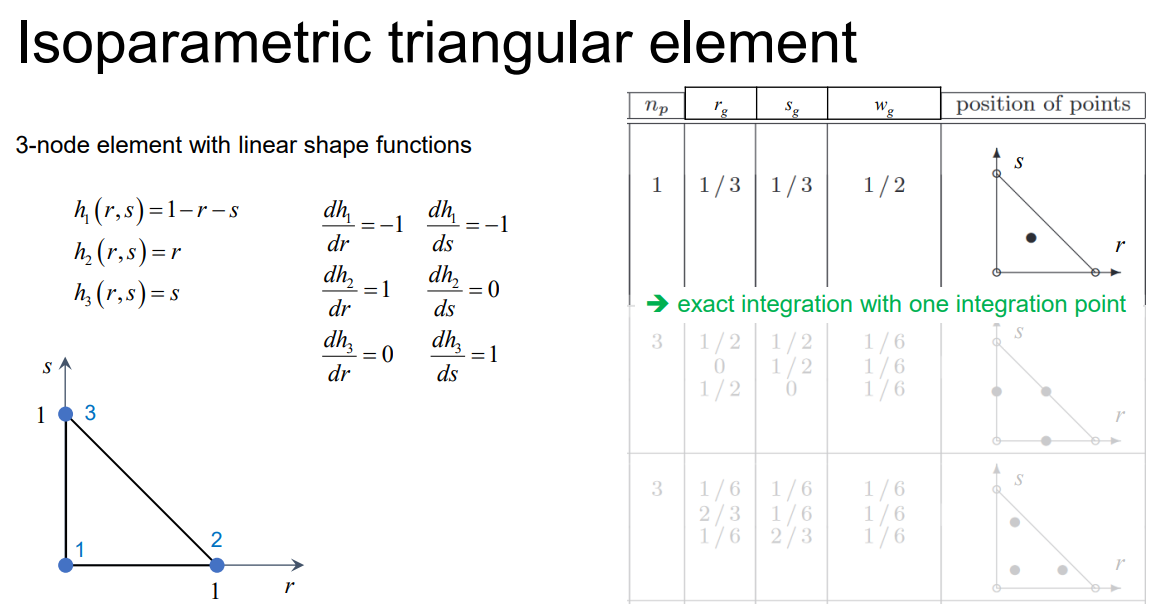

clear all; close all;

## Given parameters

E = 2.1e5;
nu = 0.3;

C = E / (1 - nu^2) * [1, nu, 0;
                      nu, 1, 0;
                      0,  0, (1 - nu) / 2];

## Model definition

Lx = 1.5;
Ly = 2/3;
nodes = [0,0; Lx,0;
         0,Ly; 1.8,0.5; 2*Lx,Ly; 
         0,2*Ly; Lx,2*Ly; 2*Lx,2*Ly]; 
elements = [1,2,3;
            3,2,4;
            3,4,6;
            6,4,7;
            7,4,5;
            7,5,8];

% plotElements(nodes, elements, 'Model'); grid on;
% plotQuadraticElements(nodes, elements); grid on;

% Helper variables
nNodes = size(nodes, 1);
dofPerNode = 2;

nElements       = size(elements, 1);
nodesPerElement = size(elements, 2);
dofPerElement   = dofPerNode * nodesPerElement;
elementDOFs     = globalElementDOFs(elements, 2);

## Generalized stiffness assembly

Set up system matrices

K = zeros(dofPerNode * nNodes);
u = zeros(dofPerNode * nNodes, 1);
f = zeros(dofPerNode * nNodes, 1);

% Set up stiffness matrix by looping over elements
integrationOrder = 1;
for e = 1 : nElements
    elementNodes = nodes(elements(e, :), :);
    KE = elementStiffness(C, elementNodes, integrationOrder);
    
    % Use element connectivity to add element stiffness to global stiffness matrix
    K(elementDOFs(e, :), elementDOFs(e, :)) =   K(elementDOFs(e, :), elementDOFs(e, :)) + ...
                                                KE; 
end

% Load
f([10,16]) = (700*2/3)/2;

% Solve system
fixeddofs = [1,2,4];
freedofs = setdiff(1 : nNodes * dofPerNode, fixeddofs);

u(freedofs) = K(freedofs, freedofs) \ f(freedofs);
u([15,16])  % -0.0093; 0.0243

ans =    -0.0093
    0.0243


% Plot displacement as x0 + u
scale = 3;
uNodes = transpose(reshape(u, dofPerNode, nNodes));
uMagnitude = vecnorm(uNodes, 2, 2);

## Additional functions

function [xg, wg] = gaussianPoints2D(n)
    % Return integration points and weights for 2D gauss integration of order n
    % INPUT
    %   n (scalar)      OPTIONAL, order for integration, default: 2
    % OUTPUT
    %   xg (array)      Gaussian points in 2D
    %   wg (array)      Combined weights for 2D integration points

    if nargin < 1
        n = 2;
    end
    
    switch n
        case 1
            xg = [1/3, 1/3];
            wg = 1/2;
        otherwise
            error('Integration points for order %d not implemented', n);
    end
end

function elementDOFs = globalElementDOFs(elements, dim)
    % Return global DOFs for elements
    % INPUT
    %   elements (array)    nodes per element as (nElements x nodesPerElement) array
    %   dim (scalar)        dimension
    % OUTPUT
    %   elementDOFs (array) global DOFs per element as (nElements x (dim * nodesPerElement)) array

    switch dim
        case 1
            elementDOFs = elements;
        case 2
            nodes = reshape(elements', numel(elements), 1);
            elementDOFs = [2 * nodes - 1, 2 * nodes]';
            elementDOFs = transpose(reshape(elementDOFs(:), 2 * size(elements, 2), size(elements, 1)));
        otherwise
            error("not implemented");
    end
end

function KE = elementStiffness(C, elementNodes, integrationOrder)
    % Compute element stiffness matrix
    % INPUT
    %   C (array)                   Constitutive matrix
    %   elementNodes (array)               Nodes for element
    %   integrationOrder (scalar)   Integration order for gauss quadrature
    % OUTPUT
    %   KE (array)                  Element stiffness matrix

    KE = zeros(size(elementNodes, 1) * size(elementNodes, 2));

    [xg, wg] = gaussianPoints2D(integrationOrder);              % STEP1: GAUSS POINTS

    % Integrate stiffness
    [~, dh] = linearShapeFunctions(xg(1), ...                   % STEP2: DERIVATIVES OF SHAPE FUNCTIONS w.r.t. r,s,t
                                   xg(2));              
    J = dh * elementNodes;                                      % STEP3: JACOBIAN

    dhdx = J \ dh; % inv(J) * dh;
    B = bMatrix(dhdx);                                          % STEP4: DERIVATIVES OF SHAPE FUNCTIONS w.r.t. x,y,z -> B matrix

    KE = KE + wg * B' * C * B * abs(det(J));                    % STEP5: STIFFNESS MATRIX

end

% Shape functions
function [h, dh] = linearShapeFunctions(r, s)
    % Evaluate shape functions for linear triangular element
    % INPUT
    %   r (array)   r coordinate for evaluation of shape functions and derivatives in natural coordinates
    %   s (array)   s coordinate for evaluation of shape functions and derivatives in natural coordinates
    % OUTPUT
    %   h (array)           Shape functions at (r, s), row per given point
    %   dh (array)          Derivatives of shape functions at first (r, s)

    h1 = 1-r-s;
    h2 = r;
    h3 = s;

    dh1dr = -1;
    dh1ds = -1;

    dh2dr =  1;
    dh2ds =  0;
    
    dh3dr =  0;
    dh3ds =  1;

    h = [h1, h2, h3];

    dh = [dh1dr, dh1ds;
          dh2dr, dh2ds;
          dh3dr, dh3ds]';
end

% H matrices
function H = hMatrix(r, s)
    % Evaluate H matrix for linear quadrilaterial element
    % INPUT
    %   r (array)   r coordinate for for evaluation of shape functions and derivatives in natural coordinates
    %   s (array)   s coordinate for for evaluation of shape functions and derivatives in natural coordinates
    % OUTPUT
    %   H (array)   B matrix for linear quadrilateral element in natural coordinates

    h = linearShapeFunctions(r, s);
    H = [h(1), 0, h(2), 0, h(3), 0, h(4), 0;
         0, h(1), 0, h(2), 0, h(3), 0, h(4)];
end

function B = bMatrix(dhdxy)
    % Evaluate B matrix for linear triangular element
    % INPUT
    %   dhdx (array)   Derivatives of shape functions with respect to physical coordinates
    % OUTPUT
    %   B (array)      B matrix for linear triangular element

    dh1dx = dhdxy(1,1);
    dh1dy = dhdxy(2,1);
    
    dh2dx = dhdxy(1,2);
    dh2dy = dhdxy(2,2);
    
    dh3dx = dhdxy(1,3);
    dh3dy = dhdxy(2,3);

    % Assign dh entries to B matrix
    B = [dh1dx, 0    , dh2dx, 0    , dh3dx, 0    ;
         0    , dh1dy, 0    , dh2dy, 0    , dh3dy;
         dh1dy, dh1dx, dh2dy, dh2dx, dh3dy, dh3dx];
end